# TIO Tables Example

#### Define TIO table and graph

n=4;  % Number of nodes
ns=1; % Source node
nt=6; % Sink node
T=[0 36 0 0 0 0;
   0 0 0 16 8 0
   0 0 0 6 3 0
   0 0 10 0 0 10
   0 0 0 0 0 8
   0 0 0 0 0 0]

T =      0    36     0     0     0     0
     0     0     0    16     8     0
     0     0     0     6     3     0
     0     0    10     0     0    10
     0     0     0     0     0     8
     0     0     0     0     0     0


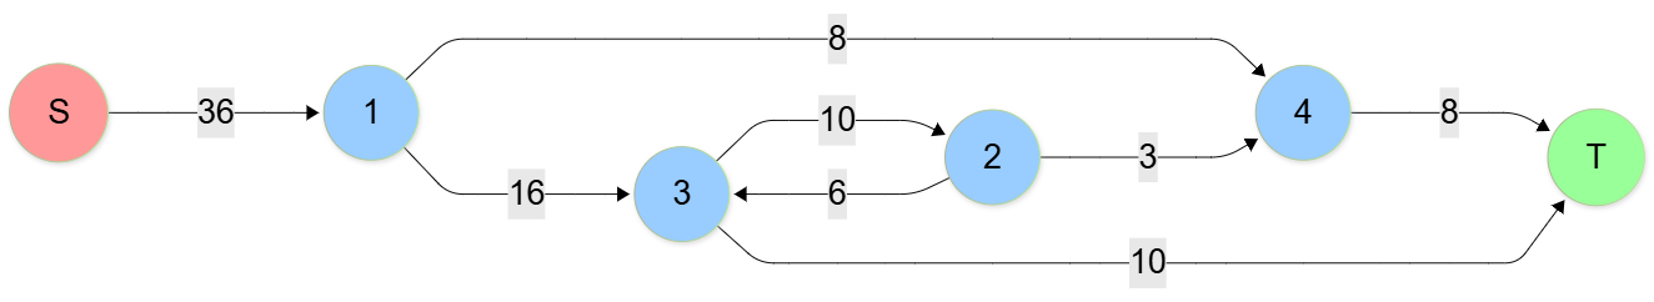

#### Graph Reachability

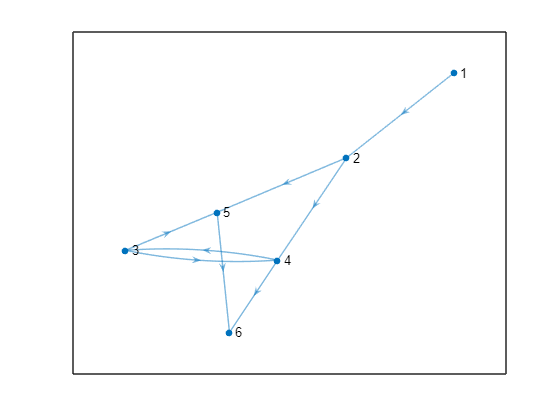

g = digraph(T);
plot(g)

s=distances(g,ns,'Method','unweighted')

s =      0     1     3     2     2     3


t=distances(flipedge(g),nt,'Method','unweighted')

t =      3     2     2     1     1     0


#### Allocation Matrix

tmp=sum(T,2); x=tmp(2:end-1)';
dx=1./x;
B = T(2:end-1,2:end-1) .* dx';

#### Consumption Matrix

A = T(2:end-1,2:end-1) .* dx

A =          0         0    0.8000    1.0000
         0         0    0.3000    0.3750
         0    1.1111         0         0
         0         0         0         0


#### Check Spectral Radius and determinant

rhoA=max(abs(eig(A)))

rhoA = 0.5774

rhoB=max(abs(eig(B)))

rhoB = 0.5774

detA=det(eye(n)-A)

detA = 0.6667

detB=det(eye(n)-A)

detB = 0.6667

#### Compute Inverses

invA=eye(n)/(eye(n)-A)

invA =     1.0000    1.3333    1.2000    1.5000
         0    1.5000    0.4500    0.5625
         0    1.6667    1.5000    0.6250
         0         0         0    1.0000


invB=eye(4)/(eye(n)-B)

invB =     1.0000    0.5000    1.0000    0.5000
         0    1.5000    1.0000    0.5000
         0    0.7500    1.5000    0.2500
         0         0         0    1.0000


invA1= x' .* invB .* dx

invA1 =     1.0000    1.3333    1.2000    1.5000
         0    1.5000    0.4500    0.5625
         0    1.6667    1.5000    0.6250
         0         0         0    1.0000


#### Compute cost and prices

z=T(1,2:end-1)/(eye(n)-B)

z =    36.0000   18.0000   36.0000   18.0000


c=z./x

c =     1.5000    2.0000    1.8000    2.2500


#### Compute Irreversibilty

tmp=sum(T,1); y=tmp(2:end-1);
d=y-x

d =     12     1     2     3


#### Compute Irreversibility-Cost Table

zd=[x; d.*invB]

zd =    24.0000    9.0000   20.0000    8.0000
   12.0000    0.5000    2.0000    1.5000
         0    1.5000    2.0000    1.5000
         0    0.7500    3.0000    0.7500
         0         0         0    3.0000


z=sum(zd,1)

z =    36.0000   11.7500   27.0000   14.7500


#### Compute Irreversibility-Cost Table (prices)

cd=[ones(1,n); (y./x-1) .* invA]

cd =     1.0000    1.0000    1.0000    1.0000
    0.5000    0.1481    0.1200    0.5625
         0    0.1667    0.0450    0.2109
         0    0.1852    0.1500    0.2344
         0         0         0    0.3750


c=sum(cd,1)

c =     1.5000    1.5000    1.3150    2.3828
